# ME 4501 Lab 9: Time Response and System Identification 

# Dr. Ayse Tekes

**Due: A week after the lab. I will be grading your lab report individually in the beginning of the class.**

**Please watch the **[**video**](https://youtu.be/F1nJ0ndgMuU)** before the lab starts.**

**Objectives**

- Obtaining the transfer function of Quanser Qube experimentally using step response and theory (First Order Systems)

- Validating the mathematical model

**A. Time Response of First Order Systems**

Step response modeling is also known as bump test, is a simple test based on the step response of a stable system. A step input is given to the system and its response is recorded.

The transfer function of a first order system in its general form is:

$\mathit{\mathbf{G}}\left(\mathit{\mathbf{s}}\right)=\frac{\mathit{\mathbf{K}}}{\tau \mathit{\mathbf{s}}+1}$         (1)

where *K* is the DC gain and $\tau$ is the time constant. While *K*, the DC gain of the system, will determine the size of steady state response when the input settles out to a constant value, 𝜏, the time constant, will determine how quickly the system moves toward steady state.

**Example: **Let's design a first order system with K=5 rad/V, and $\tau$=0.05 s. The the transfer function using Eqn.1 becomes:

K=5; tau=0.05;
G=tf(K,[tau 1])
step(G)

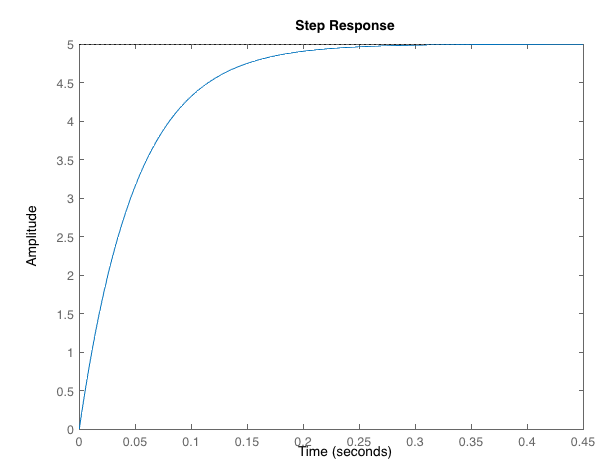

As you see from the figure above, a first oder system doesn't have an overshoot and does not exhibit any oscillatory behavior. 

**B. System Identification Using Step Response: **

If the step response of a system is obtained experimentally, then data can be used to find the unknowns of the system such as *K* and $\tau$.

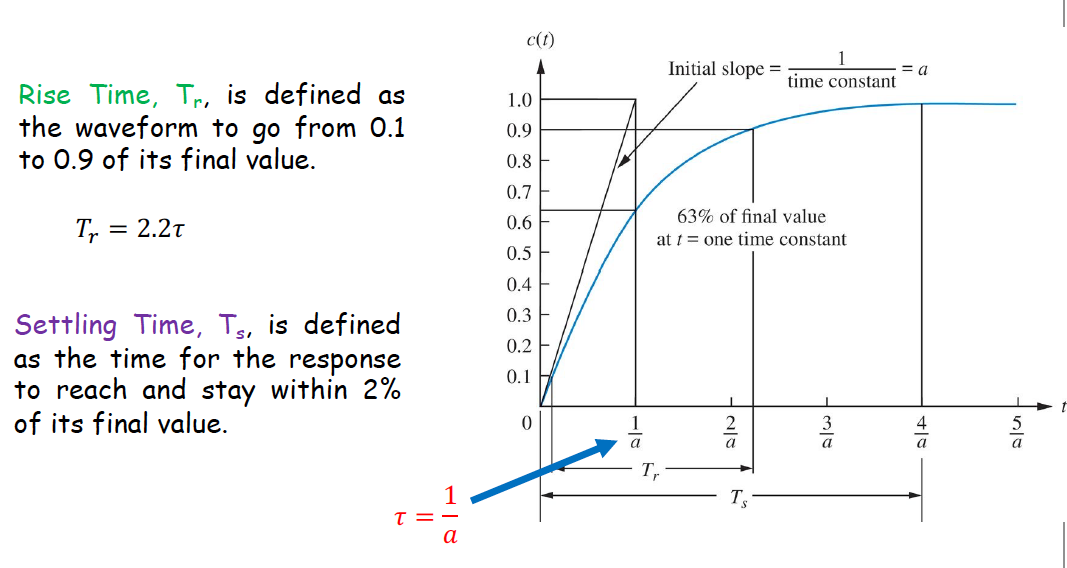

The unknowns such as *K* and $\tau$, 

- K is the final value of the step response

- $T_s =4\tau$ . Settling time ($T_s$) is the time required for the signal to reach to its 98% of the final value.

**C. Step Response of Quanser Qube**

**1.** Design a model that applies a step of 2 V to the motor and reads the servo velocity using the encoder as shown in below. Model can be uploaded from D2L.

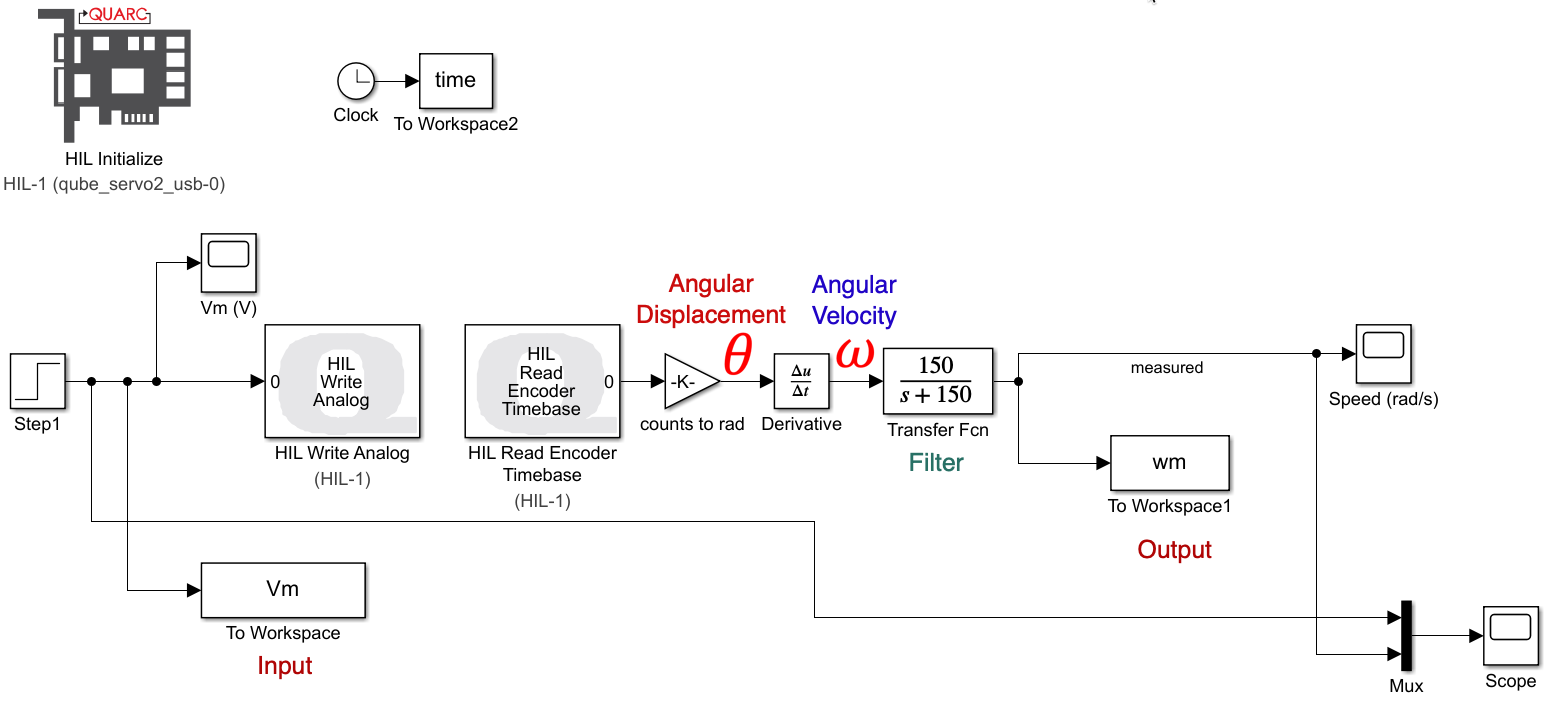

**2. **Apply 2 V step to the servo at 1 second and copy paste the scope of the input and speed below.

**3.** Share data within your group so each of you will have the data to plot the response in MATLAB figure by writing a code below. 

For example, you can setup the scopes to save the measured load/disk speed and motor voltage to the MATLABr workspace in the variables data_wm and data_vm, where the data_wm(:,1) is the time vector and data_wm(:,2) is the measured speed. Or alternatively, you can use the exported datas Vm and wm.

**4.** Find the steadystate gain using the measured step response. 

Hint: Use the Cursor Measurements tool in the SIMULINK Scope or the Data Tips tool in the MATLAB figure to take measurements directly from the response plots.

**5.** Find the time constant from the obtained response.

**C. Model Validation**

**1.** To check if your derived model parameters K and τ are correct, modify the Simulink diagram to include a Transfer Fcn block with the first order model in Equation 1, as shown in the figure below. Connect both the measured and simulated QUBE responses to the scope using a Mux block (from the Signal Routing category). Build and run your QUARC controller. Attach a MATLAB figure displaying both the measured and simulated response in one plot, as well as in the input voltage.

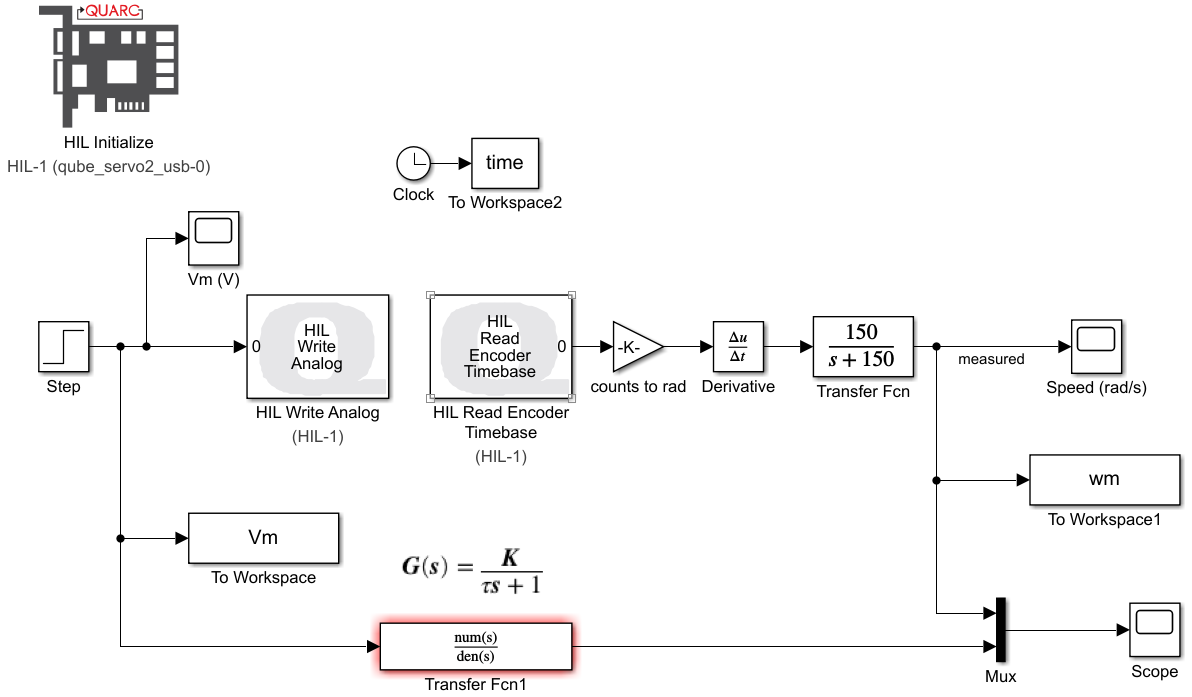

**D. System identification Using System Identification Toolbox**

**The picture below shows all the steps to be followed for system identification. You can modify the size of the image below to see the details. **

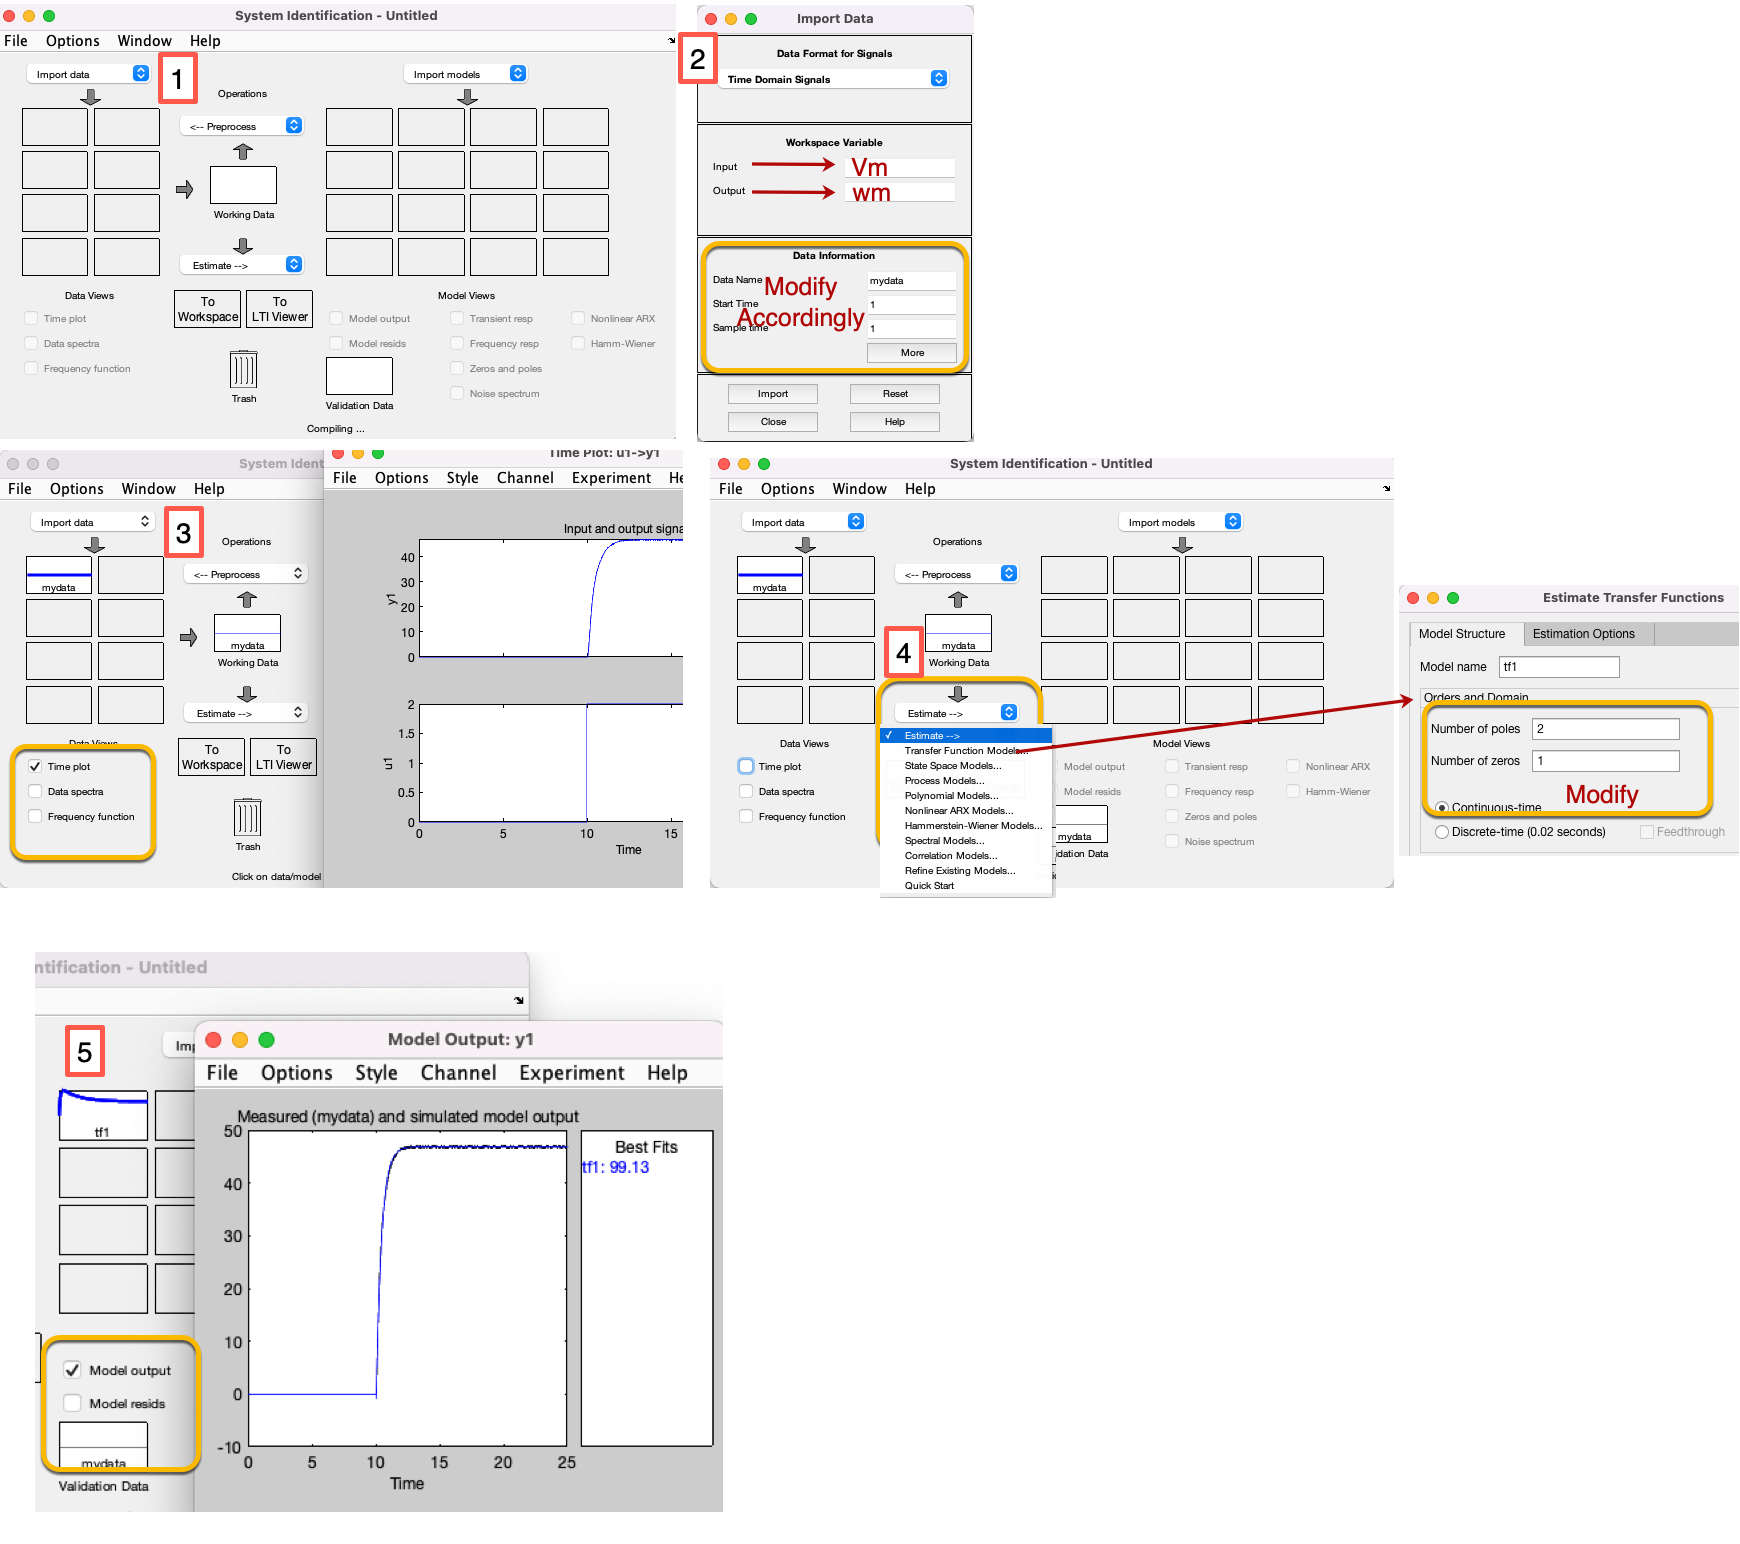

**1. **Find the sampling time by typing as a command: time(2)-time(1) 

**2.** Type in SystemIdentification as a command.

**3.** Click on Import Data and select Time Domain Signals from dropdown menu. Update the inputs accordingly such that Start Time is 0 and Sample time will be calculated from Step 1.

**4.** Then click on Import and close the subwindow.

**5.** Select Time Plot on the main SystemIdentification Toolbox to plot the time response. This is to check and see if the input and output are imported correctly.

**6.** Click on Estimate and then select Transfer Function from the dropdown menu.    

**7.** Enter the number of zeroes and poles for a First Order System Transfer Function accordingly.

**8.** Then click on Estimate.

**9. **Select Model Output to see the fitted transfer function as well as how much of a fit the estimated function is. If it's higher than 95%, then it is good.

**10.** Then drag tf1 to Workspace so that you can see the details of the function

**11.** If you type in name of the estimated function as a command, you will have all the information of the transfer function.

**12.** Finally, add the transfer function to the model you created in the former section (Model Validation) and compare the experimental, theoretical transfer function, and the fitted transfer function by adding the scope or figure image.

**E. Discussion**

Did you model the parameters K and $\tau$ correctly? Explain